clc;
clear all;

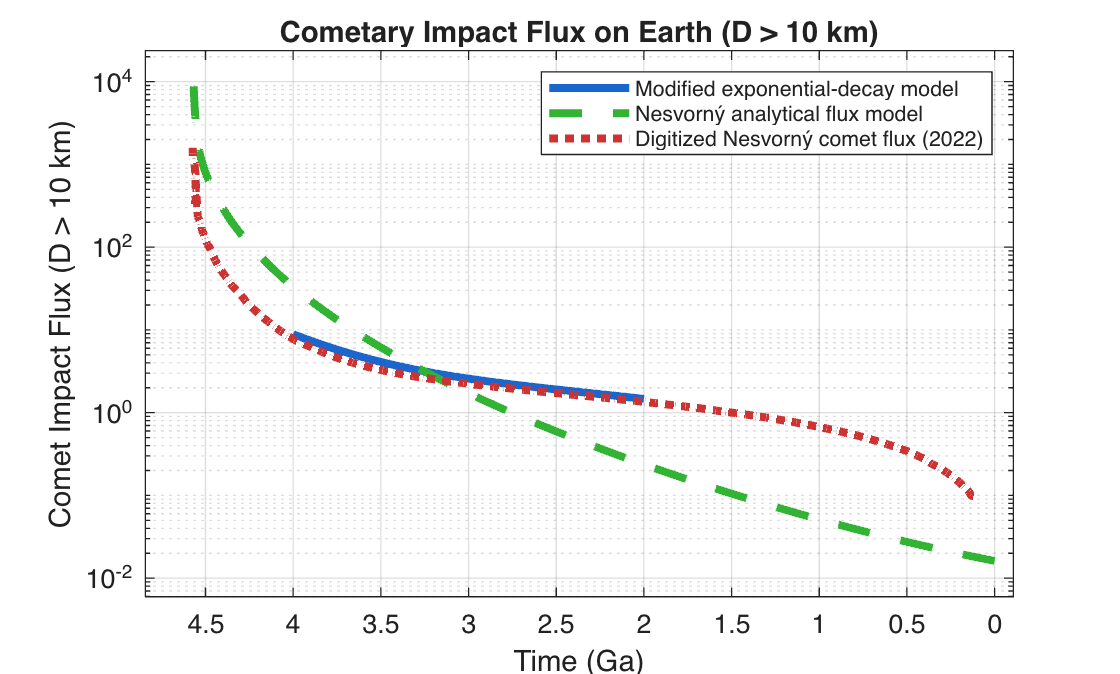

%% 1. Comet Impact Flux Models

%% Modified exponential-decay comet flux model (used for 4–2 Ga interval)
% This is a simplified analytic representation of the cometary bombardment
% that decreases smoothly through early Earth history.
a = 0.0001466;
b = 2.655;
c = 0;
d = 10.16;

t1 = linspace(4, 2, 500);   % time in billions of years ago (Ga)

% Flux model: a*exp(b*t) + c*exp(d*t) + linear decay term
F_com = a.*exp(b.*t1) + c.*exp(d.*t1) + t1 .* 0.7183;

figure;
plot(t1, F_com, 'LineWidth', 3, 'LineStyle','-', 'Color',[0.1 0.4 0.8]); 
hold on;

%% Nesvorný et al. (2022) analytical comet-flux model
% This model includes two short-timescale decays plus a persistent
% background flux. Time is handled in Myr, so we convert properly.
F1 = 6.5e3;
F2 = 6.5e3;
tau1 = 7;      
tau2 = 13;     
alpha1 = 1;    
alpha2 = 0.44; 
F3 = 4e-3;     
Cs = 1;

t2 = linspace(4570, 0, 2000);   % time before present in Myr (4.57 Ga)

% Nesvorný flux prescription
F = Cs * ( ...
    F1 .* exp(-(t2./tau1).^alpha1) + ...
    F2 .* exp(-(t2./tau2).^alpha2) + ...
    F3 );

% Convert Myr → Ga and flip so that older time (4.5 Ga) is on the left
plot(flip(t2/1000), F, 'LineWidth', 3, 'LineStyle','--', ...
    'Color',[0.2 0.7 0.2]); 
hold on;


%% Nesvorný et al. (2022) digitized comet-flux curve
% Loaded directly from the CSV table extracted from Fig. 4 of that paper.
nesvornyTable = readtable("supp_info_data_files/nesvorny_2022_asteroid_and_comet_curve.csv", ...
                          "VariableNamingRule", "preserve");

nesvorny_comet = nesvornyTable{:, 1:2};       % first two columns = comet curve

plot(nesvorny_comet(:,1), nesvorny_comet(:,2), ...
    'LineWidth', 3, 'LineStyle', ':', 'Color',[0.8 0.2 0.2]);
hold on;


%% Plot formatting and labels
% Time axis is reversed (4.5 Ga → left, present → right)
% Flux is logarithmic because values span several orders of magnitude.
title('Cometary Impact Flux on Earth (D > 10 km)');
xlabel('Time (Ga)');
ylabel('Comet Impact Flux (D > 10 km)');

xlim([0, 4.5]);
ylim([1E-2, 1E4]);

set(gca, 'YScale', 'log');
set(gca, 'XDir', 'reverse');

grid on;
box on;
hold off;

legend( ...
    'Modified exponential-decay model', ...
    'Nesvorný analytical flux model', ...
    'Digitized Nesvorný comet flux (2022)', ...
    'Location','northeast', 'FontSize', 8);

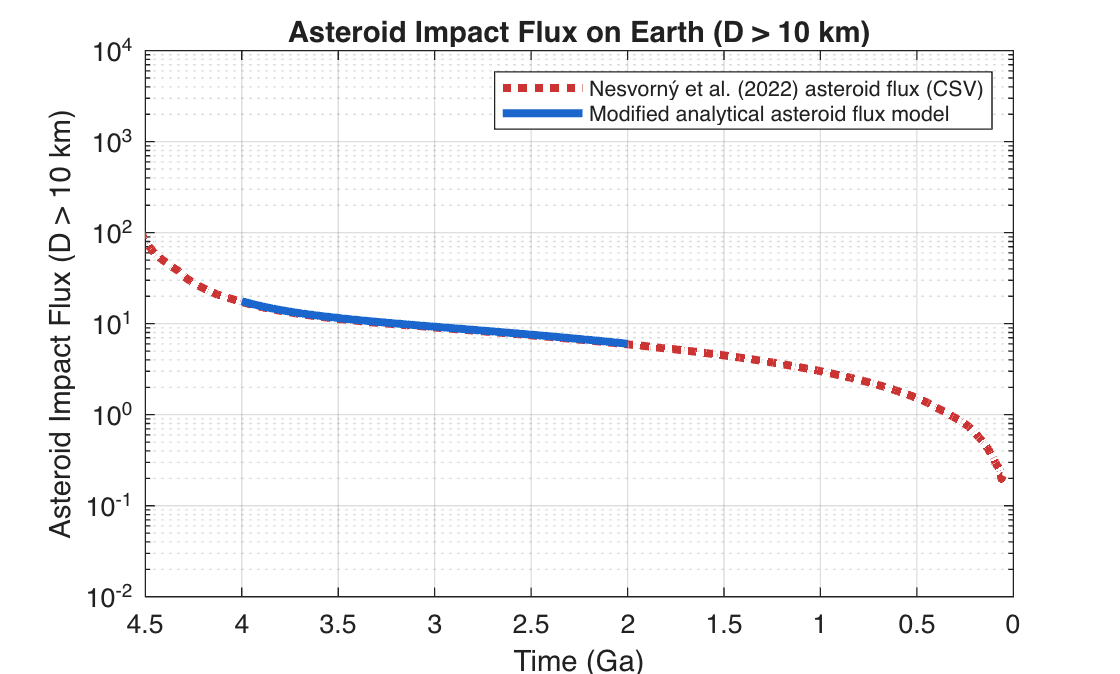

%% 2. Nesvorný et al. (2022) asteroid-flux data
% These are the digitized points from Fig. 4 in Nesvorný et al. (2022),
% representing the inferred flux of asteroid impacts (D > 10 km) over time.
nesvorny_asteroid = nesvornyTable{:, 3:4};   % columns 3–4 = asteroid curve
nesvorny_asteroid = sortrows(nesvorny_asteroid, 1);   % sort by increasing time

%% Asteroid impact-flux model based on Nesvorný et al. (2022)
% This simple analytic model captures:
%   – a rapidly decaying early heavy-bombardment term
%   – a long-lived low-level background flux
F_ast_1_10km = 225;        % initial heavy-bombardment amplitude
F_ast_2_10km = 3E-3;       % long-term background flux
tau = 65.0;                % decay timescale in Myr

t = linspace(2, 4, 500);   % time in Ga (2 → 4 Ga)

% Convert geological time (Ga) into time-before-present in Myr:
%   dt_Myr = 0 Myr at 4.57 Ga and increases toward present.
dt_Myr = (4.57 - t) * 1000;

% Flux equation: heavy-bombardment decay + long-term residual flux
F_ast = F_ast_1_10km .* exp(-(dt_Myr/tau).^0.6) ...
      + F_ast_2_10km .* (4570 - dt_Myr);

figure; clf; hold on;
plot(nesvorny_asteroid(:,1), nesvorny_asteroid(:,2), ...
    'LineWidth', 3, 'LineStyle', ':', 'Color',[0.8 0.2 0.2]);

plot(t, F_ast, ...
    'LineWidth', 3, 'LineStyle','-', 'Color',[0.1 0.4 0.8]);

%% Plot formatting
% Logarithmic y-axis captures the large dynamic range of flux values.
% Time axis reversed so ancient epochs (4.5 Ga) appear on the left.
title('Asteroid Impact Flux on Earth (D > 10 km)');
xlabel('Time (Ga)');
ylabel('Asteroid Impact Flux (D > 10 km)');
set(gca, 'YScale', 'log');
set(gca, 'XDir', 'reverse');
xlim([0 4.5]);
ylim([1E-2 1E4]);
grid on;
box on;


%% Legend
legend( ...
    'Nesvorný et al. (2022) asteroid flux (CSV)', ...
    'Modified analytical asteroid flux model', ...
    'Location','northeast', 'FontSize', 8);

hold off;

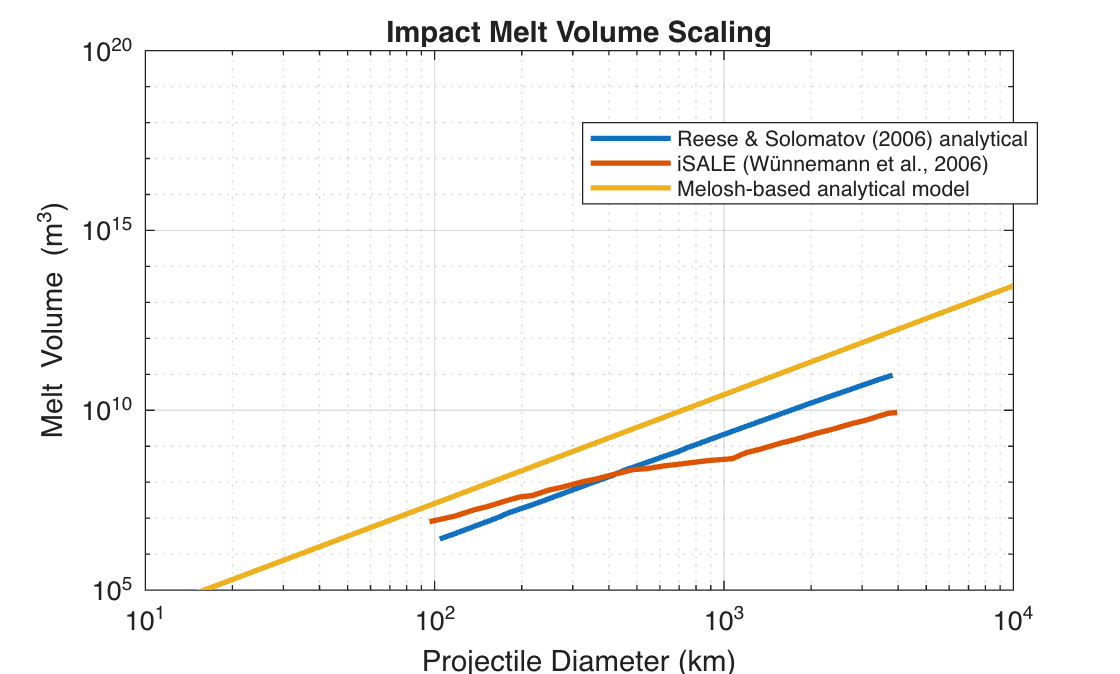

%% 3. Impact melt scaling: analytical model vs iSALE results

% Projectile size range (km)
% Using a wide range to capture small → basin‐forming impactors.
d_vals = linspace(1, 10000, 200);

% Fixed impact conditions
vel_proj = 18;        % projectile velocity in km/s
ang_proj = pi/4;      % 45° impact angle (typical median angle)

% Preallocate array for melt volumes
vol_melt_vals = zeros(size(d_vals));

% Compute melt volume for each projectile size
% gen_impact_melt returns melt volume in m^3 → convert to km^3
for i = 1:length(d_vals)
    [~, ~, ~, ~, vol_melt, ~] = gen_impact_melt(d_vals(i), vel_proj, ang_proj);
    vol_melt_vals(i) = vol_melt / (1000^3);   % convert m^3 → km^3
end

figure; clf; hold on;
set(gca,'XScale','log','YScale','log');   % log–log axes for SFD comparison

%% Marchi et al. (2014) comparison data
% These two datasets represent:
%   – analytical melt scaling from Reese & Solomatov (2006)
%   – numerical hydrocode (iSALE) melt production estimates
marchiTable1 = readtable("supp_info_data_files/marchi_2014_melt_volume_1.csv");

marchi_1_set1 = marchiTable1{:, 1:2};   % analytical model curve
marchi_1_set2 = marchiTable1{:, 3:4};   % iSALE melt‐volume curve

% Literature curves (log–log)
loglog(marchi_1_set1(:,1), marchi_1_set1(:,2), 'LineWidth', 2, ...
       'DisplayName', 'Reese & Solomatov (2006) analytical'); 

loglog(marchi_1_set2(:,1), marchi_1_set2(:,2), 'LineWidth', 2, ...
       'DisplayName', 'iSALE (Wünnemann et al., 2006)');


%% Your melt‐scaling model (Melosh‐based)
% This shows how the analytical scaling from gen_impact_melt compares
% to both the analytical and iSALE melt‐volume estimates.
loglog(d_vals, vol_melt_vals, 'LineWidth', 2, ...
       'DisplayName', 'Melosh-based analytical model');


%% Plot formatting
legend('show', 'Location', 'northwest', 'FontSize', 8);

title('Impact Melt Volume Scaling');
xlabel('Projectile Diameter (km)');
ylabel('Melt Volume (m^3)');

xlim([1E1 1E4]);
ylim([1E5 1E20]);

grid on;
box on;
hold off;

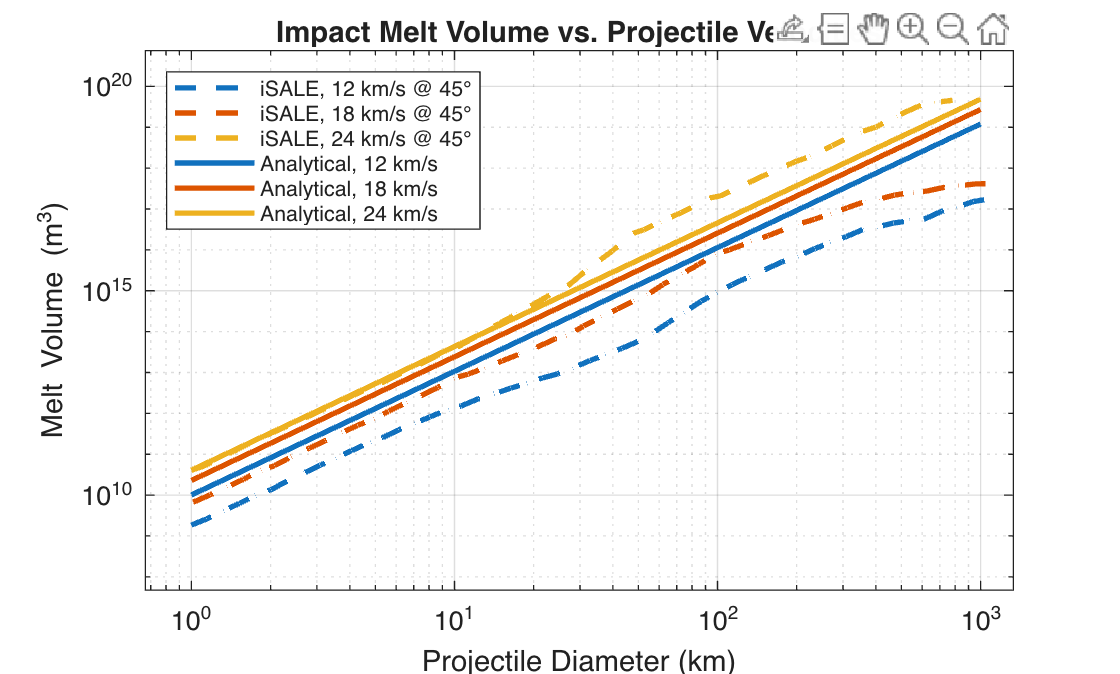

%% 4. Impact melt volume comparison across different projectile velocities
% The goal is to show how velocity affects melt production for a wide range
% of projectile sizes.

% Load Marchi et al. (2014) melt-volume datasets for three velocities
marchiTable2 = readtable("supp_info_data_files/marchi_2014_melt_volume_2.csv", ...
    "VariableNamingRule","preserve");

marchi_2_set1 = marchiTable2{:, 1:2};   % iSALE: ~12 km/s
marchi_2_set2 = marchiTable2{:, 3:4};   % iSALE: ~18 km/s
marchi_2_set3 = marchiTable2{:, 5:6};   % iSALE: ~24 km/s


%% Compute analytical melt scaling for each velocity
% Projectile diameter range (km)
d_vals = linspace(1, 1e3, 200);

% Fixed impact angle (45°)
ang_proj = pi/4;

% Velocity set to match iSALE curves
vel_list = [12, 18, 24];  % km/s
numV = length(vel_list);

% Allocate array for analytical melt curves
vol_melt_sets = zeros(numV, length(d_vals));

% Compute melt volume using gen_impact_melt (units returned in m^3)
for v = 1:numV
    vel_proj = vel_list(v);
    for i = 1:length(d_vals)
        [~, ~, ~, ~, vol_melt, ~] = gen_impact_melt(d_vals(i), vel_proj, ang_proj);
        vol_melt_sets(v,i) = vol_melt;
    end
end

figure; clf; hold on;
set(gca,'XScale','log','YScale','log');   % log–log axes for SFD comparison

c = lines(3);
% Plot iSALE melt curves (dashed)
% Note: Marchi data are in km^3 → convert to m^3 for consistency
loglog(marchi_2_set1(:,1), marchi_2_set1(:,2)*1000^3, '--', ...
    'Color', c(1,:), 'LineWidth', 2, ...
    'DisplayName', 'iSALE, 12 km/s @ 45°');

loglog(marchi_2_set2(:,1), marchi_2_set2(:,2)*1000^3, '--', ...
    'Color', c(2,:), 'LineWidth', 2, ...
    'DisplayName', 'iSALE, 18 km/s @ 45°');

loglog(marchi_2_set3(:,1), marchi_2_set3(:,2)*1000^3, '--', ...
    'Color', c(3,:), 'LineWidth', 2, ...
    'DisplayName', 'iSALE, 24 km/s @ 45°');

% Plot analytical melt-scaling results (solid lines)
loglog(d_vals, vol_melt_sets(1,:), '-', 'LineWidth', 2, ...
    'Color', c(1,:), 'DisplayName', 'Analytical, 12 km/s');

loglog(d_vals, vol_melt_sets(2,:), '-', 'LineWidth', 2, ...
    'Color', c(2,:), 'DisplayName', 'Analytical, 18 km/s');

loglog(d_vals, vol_melt_sets(3,:), '-', 'LineWidth', 2, ...
    'Color', c(3,:), 'DisplayName', 'Analytical, 24 km/s');


%% Axis formatting and labels
xlim([1E0 1E3]);
xlabel('Projectile Diameter (km)');
ylabel('Melt Volume (m^3)');
title('Impact Melt Volume vs. Projectile Velocities');

legend('show', 'Location', 'northwest', 'FontSize', 8);

grid on;
box on;
hold off;

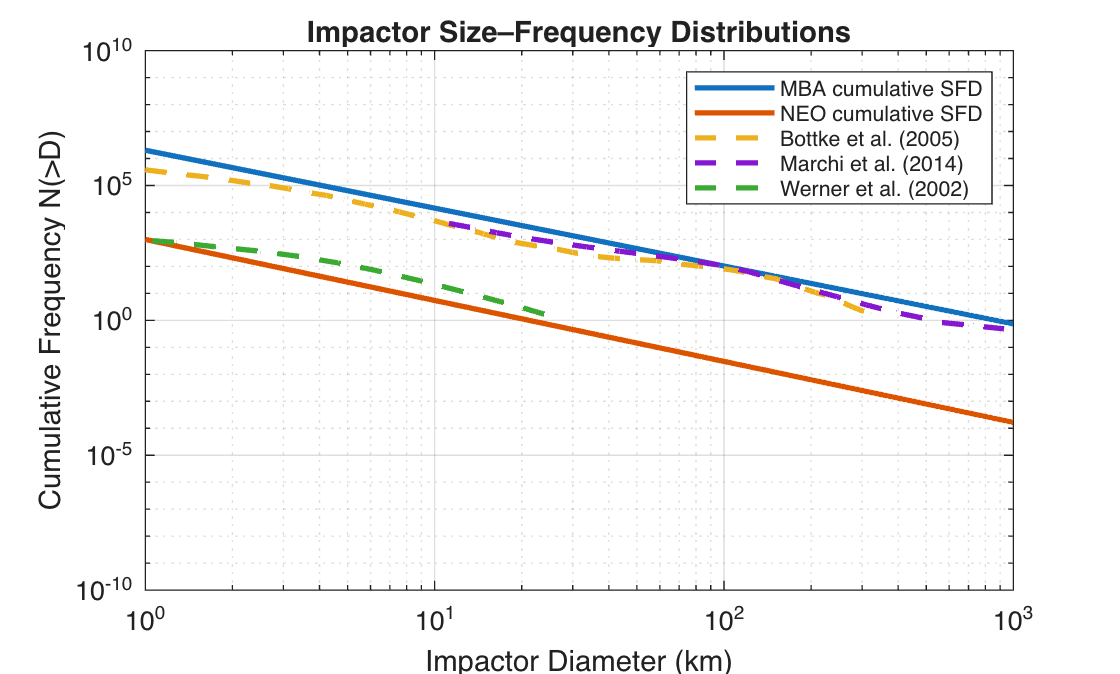

%% 5. A comparison of analytic and observational asteroid size–frequency distributions
% (MBA, NEO, Bottke, Marchi, and Werner) over diameters 1–1000 km.

% --- Projectile diameter range (km) for analytic SFD models ---
d_start = 1.0;
d_end   = 1000.0;
impactor_interval = 1;
d_edges = d_start:impactor_interval:d_end;

%% --- Analytical cumulative SFD models (MBA and NEO) ---
freq_MBA = 2.030453e6 .* d_edges.^(-2.146389);   % Main-belt asteroids
freq_NEO = 9.959719e2 .* d_edges.^(-2.260365);   % Near-Earth objects

%% --- Bottke et al. (2005) cumulative SFD curve ---
bottkeTable = readtable("supp_info_data_files/bottke_2005.csv", "VariableNamingRule","preserve");
bottke_set = bottkeTable{:,1:2};

%% --- Marchi et al. (2021) SFD curve ---
marchiTable = readtable("supp_info_data_files/marchi_2021.csv", "VariableNamingRule","preserve");
marchi_set = marchiTable{:,1:2};

%% --- Werner et al. (2001): convert H → diameter and logN → N ---
wernerTable = readtable("supp_info_data_files/werner_2001.csv", "VariableNamingRule","preserve");
werner_set = wernerTable{:,1:2};

H_w   = werner_set(:,1);          % absolute magnitude
logNw = werner_set(:,2);          % log10 cumulative frequency

pv = 0.11;                        % assumed albedo for conversion
D_w = 1329 ./ sqrt(pv) .* 10.^(-H_w/5);   % H → diameter relation
N_w = 10.^logNw;                           % convert log N to N

[D_sort, idx] = sort(D_w);       % sort curve in increasing diameter
N_sort = N_w(idx);


figure; clf; hold on;
set(gca,'XScale','log','YScale','log');   % log–log axes for SFD comparison

% Use MATLAB's "lines" color palette for clear, distinguishable curves
c = lines(5);
loglog(d_edges, freq_MBA, 'LineWidth', 2, 'Color', c(1,:), ...
    'DisplayName', 'MBA cumulative SFD');

loglog(d_edges, freq_NEO, 'LineWidth', 2, 'Color', c(2,:), ...
    'DisplayName', 'NEO cumulative SFD');

loglog(bottke_set(:,1), bottke_set(:,2), '--', 'LineWidth', 2, ...
    'Color', c(3,:), 'DisplayName', 'Bottke et al. (2005)');

loglog(marchi_set(:,1), marchi_set(:,2), '--', 'LineWidth', 2, ...
    'Color', c(4,:), 'DisplayName', 'Marchi et al. (2014)');

loglog(D_sort, N_sort, '--', 'LineWidth', 2, ...
    'Color', c(5,:), 'DisplayName', 'Werner et al. (2002)');

%% --- Axes and styling ---
title('Impactor Size–Frequency Distributions');
xlabel('Impactor Diameter (km)');
ylabel('Cumulative Frequency N(>D)');
xlim([1e0 1e3]);
ylim([1e-10 1e10]);
legend('show', 'Location', 'northeast', 'FontSize', 8);

grid on;      % major/minor grid
box on;       % full axis box
hold off;

function [mass_proj, den_proj, d_tar_trans, mass_melt, vol_melt, melt_sheet_thickness] = gen_impact_melt(d_proj, vel_proj, ang_proj)
    % GEN_IMPACT_MELT Estimates melt mass produced by an impact event
    %
    % Inputs:
    %   d_proj   - Projectile diameter (in km)
    %   vel_proj - Projectile velocity (in km/s)
    %   ang_proj - Impact angle (in radians)
    %   imp_type - Impactor type (1 = asteroid, 2 = comet)
    %
    % Output:
    %   mass_melt - Estimated mass of melt produced (in kg)
    %
    % Description:
    %   This function estimates impact melt production using a scaling law
    %   that accounts for projectile size, velocity, impact angle, and density.
    %   The target is assumed to be lunar crust (gabbroic anorthosite), and
    %   the calculation includes realistic projectile densities.

    % Convert diameter from km to m and velocity to km/s to m/s
    d_proj = d_proj  * 1000;
    vel_proj = vel_proj * 1000;

    % Assume target material as gabbroic anothorsite (typical lunar crust)
    den_tar = 3000; % kg/m^3
    
    % Determine projectile density based on impactor type
    den_proj = 3000;

    % Use input angle and standard Earth gravity
    theta_proj = ang_proj;
    g = 9.81; % m/s^2
    % Calculate volume and mass of spherical impactor
    vol_proj = (4/3) * pi * (d_proj/2).^3;
    mass_proj = den_proj .* vol_proj;
    
    % Compute kinetic energy of the impactor
    w_proj = 0.5 .* mass_proj .* vel_proj.^2;
    
    % Estimate the transient crater diameter
    d_tar_trans = 1.8 .* den_proj.^0.11 .* den_tar.^(-1/3) .* g.^(-0.22) ...
                  .* d_proj.^0.13 .* w_proj.^0.22;
    
    % Excavated mass (Melosh, 1989)
    mass_disp = mass_proj .* ...
        ( 1.6 .* (1.61 .* g .* d_proj ./ vel_proj.^2).^(-0.22) .* ...
        ((pi/8) .* (1/2.7) .* sin(theta_proj)).^(-1/3) ).^3;
    
    % Melt mass (Melosh, 1989)
    mass_melt = mass_disp .* (1.6e-7) .* (g .* d_tar_trans).^0.83 .* vel_proj.^0.33;
    
    % Melt volume (Kring, 1995)
    vol_melt = (3.9890e-8) .* pi .* (d_tar_trans.^3.83) .* vel_proj.^0.33;
    
    % Melt sheet thickness
    melt_sheet_thickness = vol_melt ./ ((pi/4) .* d_tar_trans.^2);

end